## Visualizing Quantum States

    In this lab we develop the tools that allows an intuitive visualisation of the time-dependent solutions to the quantum harmonic oscillator in phase space. 

### Modal Decomposition Tools

    We start with the analytic solutions to the definite-energy eigenvalue problem, and describe initial conditions as linear combinations of that complete basis.

    Let $\beta =\sqrt{\frac{1}{2\hbar \;}}$, and $\gamma =\sqrt{2m\omega \;}$. All lengths are described in the dimensionless units of $z_0 \;{\mathrm{m}}^{-1} ={\left\lbrack z_0^{-1} \right\rbrack }_{\textrm{SI}}^2 z_0 \;\mathrm{m}={\left\lbrack \beta \gamma \right\rbrack }_{\textrm{SI}}^2 {\left(\beta \gamma \;\right)}^{-1} \mathrm{m}=\sqrt{\frac{\hbar }{m\omega }}{\mathrm{m}}^{-1} ,$ and times in units of ${\;\left\lbrack \gamma^2 \right\rbrack }_{\textrm{SI}}^2 \;\gamma^{-2} \mathrm{s}={\left(m\omega \right)}^{-1} \;\frac{{\textrm{kg}}^2 }{2s},$ where ${\left\lbrack \cdot \right\rbrack }_{\textrm{SI}}$ denotes the SI units of the enclosed physical quantity. Note that momentum in these units is also dimensionless, described in units of ${\left\lbrack \beta \gamma^{-1} \right\rbrack }_{\textrm{SI}}^2 \beta^{-1} \gamma \;\textrm{kg}\;\frac{\mathrm{m}}{\mathrm{s}}=2\sqrt{\hbar m\omega }{\textrm{kg}}^{-1} \frac{\mathrm{s}}{\mathrm{m}}$, so that $\hbar =\frac{1}{2}$ (dimensionless). Then the $j^{\textrm{th}}$ solution to the simple harmonic oscillator is given by $\psi_j \left(z\right)={\mathcal{N}}_j H\left(z\right)\;\exp \left(-z^2 /2\right)$ where ${\mathcal{N}}_{j\;}$ is a normalization constant. 

We can plot the first few solutions as follows

plotmax=8;gridmax=1.5*plotmax;dz=.1; firstn=20;
zgrid=-gridmax:dz:gridmax;zgrid=zgrid-zgrid(floor(length(zgrid)/2)+1);
shomodes=zeros(firstn,length(zgrid)); norms=zeros(firstn,1);
for i=1:firstn
    [shomodes(i,:), norms(i)]=SHOmode(zgrid,i-1);end

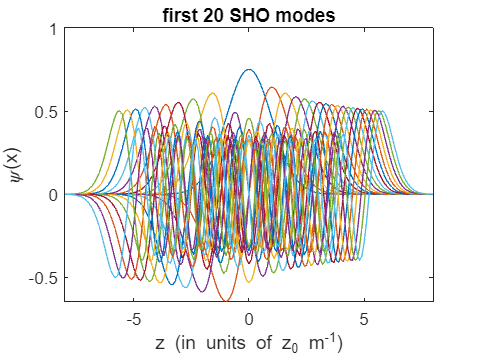

%Plotting the firstn sho eigensolutions
fig=figure(1);
plot(zgrid,shomodes,"DisplayName","shomodes");
title("first "+int2str(firstn)+" SHO modes");
xlim([-plotmax,plotmax]); 
if firstn<=5
    legend("Location","northwest");
    legend('boxoff'); end
xlabel("z (in units of z_0 m^{-1})"); ylabel("\psi(x)")

We now decompose a displaced groundstate into the first n modes to evolve it

firstncoh=8; firstnsqueezed=12;
cohstate=SHOmode(zgrid-2,0);
squeezedstate=sqrt(2)*SHOmode(2*zgrid,0); getcoeffs=@(state,firstn)gridint(zgrid,state.*shomodes(1:firstn,:)'.');
coeffssqueezed=getcoeffs(squeezedstate,firstnsqueezed);coeffscoh=getcoeffs(cohstate,firstncoh);
coh_reconstruction=coeffscoh*shomodes(1:firstncoh,:);
squeezed_reconstruction=coeffssqueezed*shomodes(1:firstnsqueezed,:);

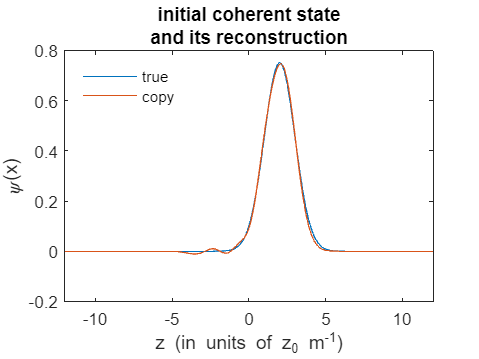

coeffs norm: 0.99945


M: 8


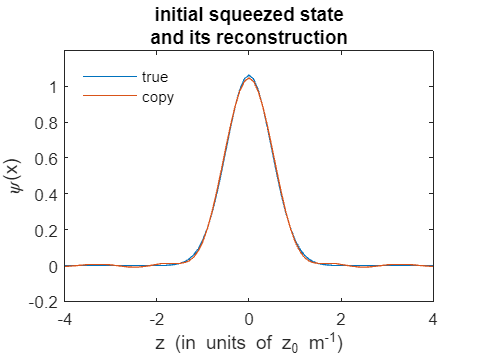

coeffs norm: 0.9997


M: 12


names=["coherent","squeezed"]; plots={[cohstate;coh_reconstruction],[squeezedstate;squeezed_reconstruction]};
Ms=[firstncoh,firstnsqueezed]; plotmaxes=[1.5,1/2]; coeffs={coeffscoh,coeffssqueezed};
for i=1:2
    figure()
    plot(zgrid,cell2mat(plots(i)));
    title({"initial "+names(i)+" state","and its reconstruction"});
    xlim(plotmaxes(i)*[-plotmax,plotmax]); legend(["true","copy"],"Location","northwest"); legend('boxoff');
    xlabel("z (in units of z_0 m^{-1})"); ylabel("\psi(x)");
    disp("coeffs norm: "+num2str(norm(cell2mat(coeffs(i)))));
    disp("M: "+int2str(Ms(i)));end

### Expectation Values

    In order to check the satisfaction of the Heisenberg uncertainty principle, we need a way to evaluate expectation values (to obtain position and momentum variances)

%Code to calculate expectation values
getmoment=@(psi,grid,n)gridint(grid,grid.^n.*abs(psi).^2);
pmax=pi/(2*dz);pgrid=linspace(-pmax,pmax,length(zgrid));pgrid=pgrid-pgrid(floor(length(zgrid)/2)+1);
dp=2*pmax/(length(zgrid)-1);
ffttop=@(psix)dz/sqrt(pi)*fftshift(fft(ifftshift(psix)));
iffttox=@(psip)dp*length(psip)/sqrt(pi)*fftshift(ifft(ifftshift(psip)));
sho0inp=ffttop(shomodes(1,:));
disp("check fft/ifft def: total probability after fft= "+num2str(gridint(pgrid,abs(sho0inp).^2)));

check fft/ifft def: total probability after fft= 1.0042


% plot(pgrid,sho0inp);xlim([-plotmax,plotmax]) %Plot for further verification of correct fft/ifft definitionsh
[states,ns]=meshgrid({shomodes(1,:),squeezedstate},{1,2});
momentsx=num2cell(cellfun(@(state,n)getmoment(state,zgrid,n),states,ns));[cohmeanx,cohmeanx2,sqmeanx,sqmeanx2]=momentsx{:};
cohstdx=sqrt(cohmeanx2-cohmeanx^2);sqstdx=sqrt(sqmeanx2-sqmeanx^2);
momentsp=num2cell(cellfun(@(state,n)getmoment(ffttop(state),pgrid,n),states,ns));[cohmeanp,cohmeanp2,sqmeanp,sqmeanp2]=momentsp{:};
cohstdp=sqrt(cohmeanp2-cohmeanp^2);sqstdp=sqrt(sqmeanp2-sqmeanp^2);
[statenames,quads]=meshgrid({'coherent','squeezed'},{'x','p'});units=["\sqrt{\hbar/(m \omega)} m^{-1}"; "2 \sqrt{\hbar m \omega} kg^{-1} s/m"];
cellfun(@(name,quad,val,unit)...
    disp("numerical "+quad+"-std for "+name+" state: "+num2str(val)+" "+unit),statenames,quads,{cohstdx,sqstdx;cohstdp,sqstdp},num2cell([units,units]));

numerical x-std for coherent state: 0.70711 \sqrt{\hbar/(m \omega)} m^{-1}
numerical p-std for coherent state: 0.35577 2 \sqrt{\hbar m \omega} kg^{-1} s/m
numerical x-std for squeezed state: 0.35355 \sqrt{\hbar/(m \omega)} m^{-1}
numerical p-std for squeezed state: 0.71153 2 \sqrt{\hbar m \omega} kg^{-1} s/m


disp("These match the exact values, giving the minimum uncertainty products (p-std)*(x-std)=hbar/2=1/4="+num2str(sqstdx*sqstdp))

These match the exact values, giving the minimum uncertainty products (p-std)*(x-std)=hbar/2=1/4=0.25156


### Evolution of coherent and squeezed states

dwt=pi/32;wtgrid=[0:dwt:6*pi]; %Defining the omega-temporal grid
plotmaxindex=@(pm)floor(length(zgrid)/2)+1+pm*ceil(plotmax/dz); %index corresponding to position values plotmax
plotgridindices=plotmaxindex(-1):plotmaxindex(1);plotgrid=zgrid(plotgridindices); %subset of the full zgrid to show plot
getmovie=@(coeffs)coeffs.*exp(-1i*wtgrid'*(1/2+[0:length(coeffs)-1]))*shomodes(1:length(coeffs),:);
movies=cellfun(getmovie,{coeffscoh,coeffssqueezed},'UniformOutput',false);[cohmovie,sqmovie]=movies{:};

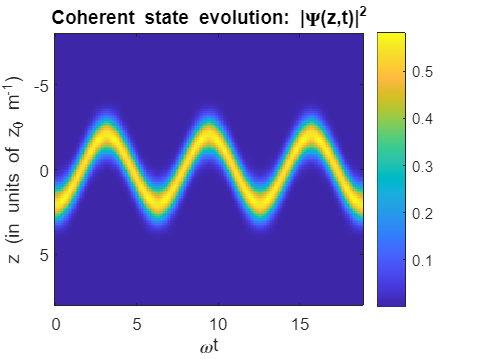

%Plottig the evolution
[movs,names]=meshgrid({cohmovie,sqmovie},{'Coherent','Squeezed'});
% cellfun(@(mov,name)...
    imagesc(wtgrid,plotgrid,abs(cohmovie(:,plotgridindices).').^2);colorbar;title("Coherent"+" state evolution: |\Psi(z,t)|^2");xlabel("\omega{t}");ylabel("z (in units of z_0 m^{-1})")%,movs,names)

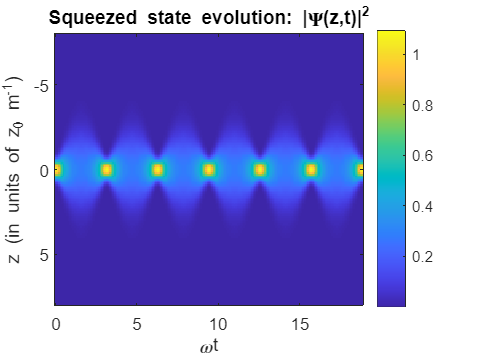

    imagesc(wtgrid,plotgrid,abs(sqmovie(:,plotgridindices).').^2);colorbar;title("Squeezed"+" state evolution: |\Psi(z,t)|^2");xlabel("\omega{t}");ylabel("z (in units of z_0 m^{-1})")

    The Shrodinger evolution can also be visualized in the momentum-basis, by converting each time frame into the momentum representation. The following is the code that does this, in addition to evaluating the uncertainy product at each time step.

pplotmax=8/sqrt(2);pplotmaxindex=@(pm)floor(length(pgrid)/2)+1+pm*ceil(pplotmax/dp);pplotgridindices=pplotmaxindex(-1):pplotmaxindex(1);
cohmovie_p=zeros(size(cohmovie,1),length(pplotgridindices));cohframe=cohstate; cohstdmov=zeros(2,size(cohmovie,1));%stds of position (row 1) and momentum (row2) as a function of time
sqmovie_p=zeros(size(cohmovie_p));sqframe=squeezedstate; sqstdmov=zeros(2,size(sqmovie,1));
for i=1:length(wtgrid)
    %Coherent state momentum update
    cohframe(plotgridindices)=cohmovie(i,plotgridindices);
    cohframep=ffttop(cohframe);
    cohmovie_p(i,:)=cohframep(pplotgridindices);
    %Squeezed state momentum update
    sqframe(plotgridindices)=sqmovie(i,plotgridindices);
    sqframep=ffttop(sqframe);
    sqmovie_p(i,:)=sqframep(pplotgridindices);
end

momentsxmov=cellfun(@(state,n)getmoment(state(:,plotgridindices),plotgrid,n),movs,ns,"UniformOutput",false);[cohmeanmovx,cohmeanmovx2,sqmeanmovx,sqmeanmovx2]=momentsxmov{:};
cohstdmov(1,:)=sqrt(cohmeanmovx2-cohmeanmovx.^2);sqstdmov(1,:)=sqrt(sqmeanmovx2-sqmeanmovx.^2);
pmovs=meshgrid({cohmovie_p,sqmovie_p},{1,2}); plotpgrid=pgrid(pplotgridindices);
momentspmov=cellfun(@(state,n)getmoment(state,plotpgrid,n),pmovs,ns,"UniformOutput",false);[cohmeanmovp,cohmeanmovp2,sqmeanmovp,sqmeanmovp2]=momentspmov{:};
cohstdmov(2,:)=sqrt(cohmeanmovp2-cohmeanmovp.^2);sqstdmov(2,:)=sqrt(sqmeanmovp2-sqmeanmovp.^2);
disp("total momentum probabilities: "+num2str(gridint(plotpgrid,abs(cohmovie_p).^2)))%Sanity check for correct momentum evolution

total momentum probabilities: 1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031      1.0031    

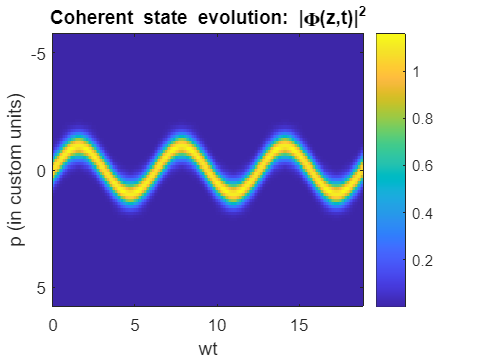

%Plotting the momentum-representation of the state evolutions
imagesc(wtgrid,plotpgrid,abs(cohmovie_p.').^2);colorbar;title("Coherent"+" state evolution: |\Phi(z,t)|^2");xlabel("wt");ylabel({"p (in custom units)"});

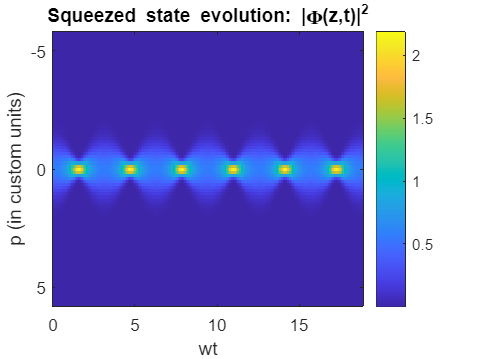

imagesc(wtgrid,plotpgrid,abs(sqmovie_p.').^2);colorbar;title("Squeezed"+" state evolution: |\Phi(z,t)|^2");xlabel("wt");ylabel({"p (in custom units)"});

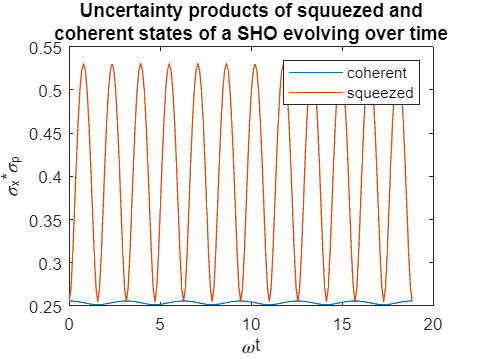

%Plotting the uncertainty product as a function of time
plot(wtgrid,[prod(cohstdmov);prod(sqstdmov)]);
title({"Uncertainty products of squuezed and","coherent states of a SHO evolving over time"});
xlabel("\omega{t}");ylabel("\sigma_x*\sigma_p");legend({"coherent","squeezed"})

    The minimum uncertainty product is not maintained for the squeezed state. According to the uncertainty product plot, the times at which it is attained correspond to times when the momentum or the position is most confined.

    From the plots of the states in the position and momentum representations, it is clear that the squeezed state has a frequency that is twice that of the coherent state. This indicates that the squeezed state is more symmetric than the coherent state.

## Wigner Function picture

    The wigner function associated with a density matrix $\hat{\rho \;}$in the choice of units described in section 1 is given by $W\left(z,p\right)=\frac{2}{\pi }\int_{-\infty \;}^{\infty \;} \langle z-u|\;\hat{\rho} \;|z+u\rangle \;e^{4\textrm{iup}} \textrm{du}$, which can be evaluated numerically by

[Wsq,modzgrid,modpgrid]=W(squeezedstate,dz);
Wcoh=W(cohstate,dz);
py=gridint(modzgrid,Wsq);
disp("Sanity check: integral of W = "+num2str(gridint(modpgrid,py)));

Sanity check: integral of W = 1.0048


%Numerical Sanity check that the Weyl transform is correct.
wignerprobx=gridint(modpgrid,Wsq.');
wignerprobp=gridint(modzgrid,Wsq);
disp("wigner x^2 moment: "+num2str(gridint(modzgrid,modzgrid.^2.*wignerprobx)));

wigner x^2 moment: 0.12592


disp("psi x^2 moment: "+num2str(sqmeanx2));

psi x^2 moment: 0.125


disp("wigner p^2 moment: "+num2str(gridint(modpgrid,modpgrid.^2.*wignerprobp)));

wigner p^2 moment: 0.50713


disp("psi p^2 moment: "+num2str(sqmeanp2));

psi p^2 moment: 0.50628


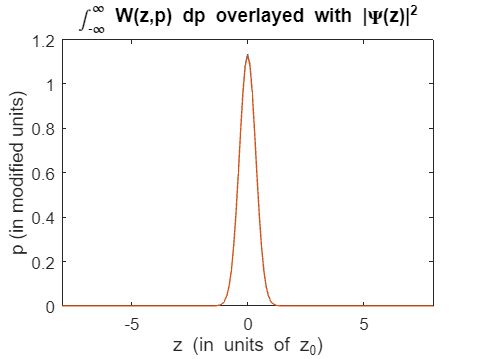

%visual sanity check
plot(modzgrid,wignerprobx);hold on;
plot(zgrid,abs(squeezedstate).^2);
title("\int_{-\infty}^{\infty} W(z,p) dp overlayed with |\Psi(z)|^2");
xlabel("z (in units of z_0)");ylabel("p (in modified units)");
xlim([-plotmax,plotmax]);hold off

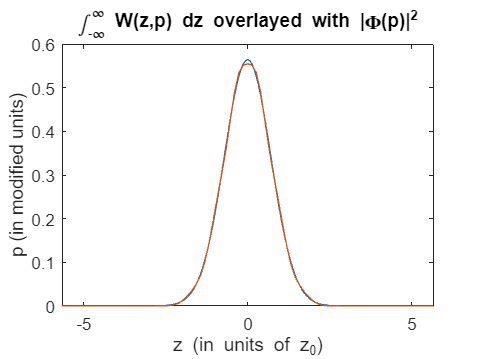


sqstate_p=sqmovie_p(1,:);
plot(modpgrid,wignerprobp);hold on;
plot(pgrid(pplotgridindices),abs(sqstate_p).^2);xlim([-pplotmax,pplotmax]);
xlabel("z (in units of z_0)");ylabel("p (in modified units)")
title("\int_{-\infty}^{\infty} W(z,p) dz overlayed with |\Phi(p)|^2");hold off

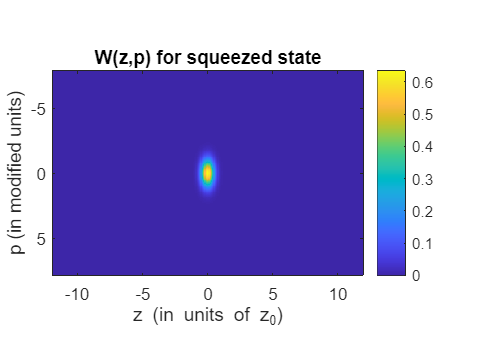

imagesc(modzgrid,modpgrid,Wsq);colorbar;title("W(z,p) for squeezed state");
xlabel("z (in units of z_0)");ylabel("p (in modified units)");
daspect([1,1,1])

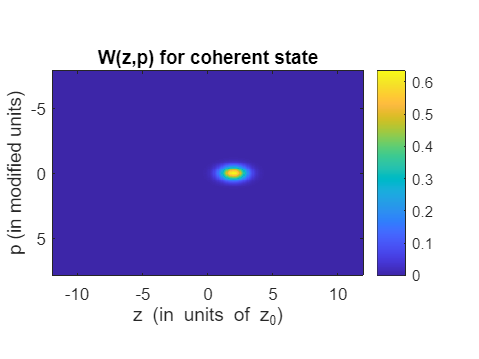

imagesc(modzgrid,modpgrid,Wcoh);colorbar;title("W(z,p) for coherent state");
xlabel("z (in units of z_0)");ylabel("p (in modified units)");daspect([1,1,1]);

    The Wigner function of the number state 1 has negative values near the origin.

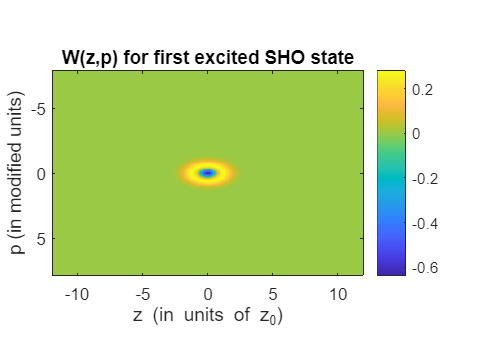

Wsho1=W(shomodes(2,:),dz);
imagesc(modzgrid,modpgrid,Wsho1);colorbar;title("W(z,p) for first excited SHO state");
xlabel("z (in units of z_0)");ylabel("p (in modified units)");daspect([1,1,1]);

    How does the Wigner function of the coherent state evolve over time?

nframes=30

nframes = 30

Wcohmovdata=zeros(size(cohmovie,2),size(cohmovie,2)-2,nframes);
for i=1:nframes
    Wcohmovdata(:,:,i)=W(cohmovie(i*floor(length(wtgrid)/nframes),:),dz);end

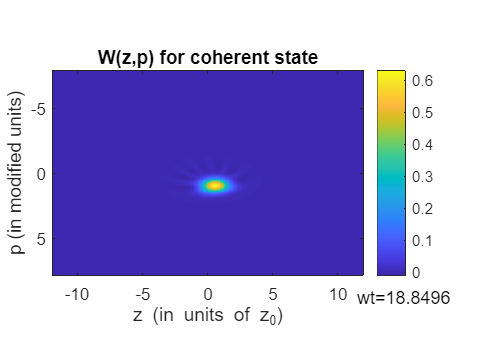

%Encoding the movie into an mp4. Open the file wignercohmov.mp4 created in
%the directory of this code file after running this section.
wignercohmov=VideoWriter("wignercohmov.mp4","MPEG-4");
wignercohmov.FrameRate=floor(nframes/3);
open(wignercohmov);
for f=1:nframes
    imagesc(modzgrid,modpgrid,Wcohmovdata(:,:,f));daspect([1,1,1]);colorbar;
    title("W(z,p) for coherent state");text(11.5,9.5,"wt="+num2str(wtgrid(floor(f*length(wtgrid)/nframes))));
    xlabel("z (in units of z_0)");ylabel("p (in modified units)");
    writeVideo(wignercohmov,getframe(gcf));end;close(wignercohmov);

%Evolution of the position and momentum means of the SHO coherent state
wignercohmeanmov=zeros(2,nframes);
for t=1:nframes
    wignercohmeanmov(1,t)=gridint(modpgrid,gridint(modzgrid,modzgrid.*Wcohmovdata(:,:,t)));
    wignercohmeanmov(2,t)=gridint(modpgrid,modpgrid.*gridint(modzgrid,Wcohmovdata(:,:,t)));end

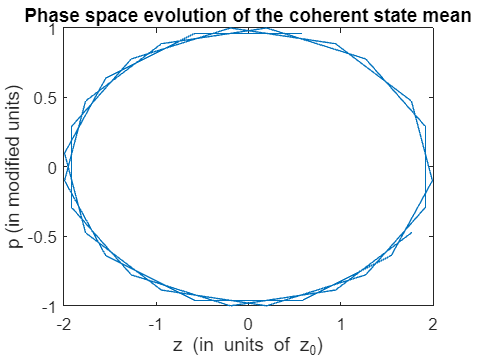

plot(wignercohmeanmov(1,:),wignercohmeanmov(2,:));
title("Phase space evolution of the coherent state mean");
xlabel("z (in units of z_0)");ylabel("p (in modified units)");

    Evolution of the Wigner funciton of a squeezed coherent state in the Wigner function picture 

cohsqstate=arrayfun(@(z)sqrt(sqrt(4/pi))*exp(-(2*(z-2))^2/2),zgrid);
cohsqcoeffs=gridint(zgrid,cohsqstate.*shomodes(1:firstnsqueezed,:)'.');
wtgridmp4=2*pi/nframes*[0:nframes-1];
cohsqstatemov=cohsqcoeffs.*exp(-1i*wtgridmp4.'*(1/2+[1:firstnsqueezed]))*shomodes(1:firstnsqueezed,:);
disp("Integral of state: "+num2str(gridint(zgrid,abs(cohsqstate).^2)));

Integral of state: 1


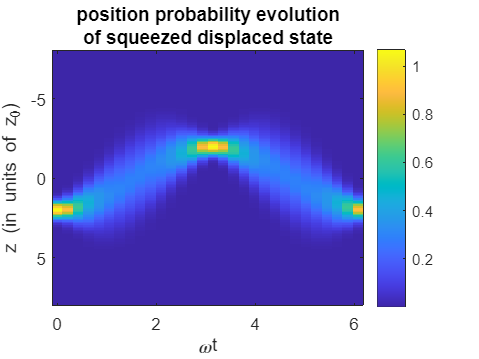

imagesc(wtgridmp4,plotgrid,abs(cohsqstatemov(:,plotgridindices).').^2);colorbar;
title({"position probability evolution","of squeezed displaced state"});
xlabel("\omega{t}");ylabel("z (in units of z_0)");

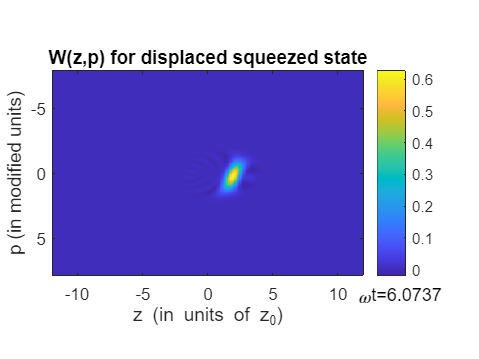

%Wigner state picture of the evolution as an mp4. Open the file wignercohsqmov.mp4 created in
%the directory of this code file after running this section.
wigneranhocohmov=VideoWriter("wignercohsqmov.mp4","MPEG-4");
wigneranhocohmov.FrameRate=floor(nframes/3);
open(wigneranhocohmov);
for f=1:nframes
    imagesc(modzgrid,modpgrid,W(cohsqstatemov(f,:),dz));daspect([1,1,1]);colorbar;
    title("W(z,p) for displaced squeezed state");text(11.5,9.5,"\omega{t}="+num2str(wtgridmp4(f)));
    xlabel("z (in units of z_0)");ylabel("p (in modified units)");
    writeVideo(wigneranhocohmov,getframe(gcf));end;close(wigneranhocohmov);

    The evolution of the quantum state is a rotation around the origin in phase space. A displacement and squeezin in z becomes a displacement and squeezing of p at $\omega t=n\frac{\pi }{2}$ where $n\in \mathbb{Z}\ldotp$ The state has mean 0 and displays antisqueezing at these times.

    Evolution of a displaced Gaussian state in an anharmonic oscillator potential. Start by defining the discretized Hamiltonian ${\left(H_{\textrm{ij}} \right)}_{\textrm{ij}}$ satisfying $\vec{\psi} \left(t\right)=e^{-i\omega \textrm{tH}} \vec{\psi} \left(0\right)\ldotp$

symize=@(M)(M+M');
hmat=diag((1/dz)^2+1/2*zgrid.^2)-(1/dz)^2/2*symize([zeros(length(zgrid)-1,1) eye(length(zgrid)-1);zeros(1,length(zgrid))]);
hmat_anho=hmat+0.02*diag(zgrid.^4);

[anhovecs,anhovalmat]=eigs(hmat_anho,firstncoh,'smallestabs');
firstnanhovals=diag(anhovalmat);
anhovecnorms=arrayfun(@(v)sqrt(gridint(zgrid,abs(v{:}.').^2)),num2cell(anhovecs,1));
normalized_anhovecs=anhovecs./anhovecnorms;
coeffsanhocoh=gridint(zgrid,cohstate.*normalized_anhovecs');
wtanhogrid=[0:.5:250];
anhocohmovie=coeffsanhocoh.*exp(-1i*wtanhogrid.'*firstnanhovals.')*normalized_anhovecs.';

%Evaluating the evolution of means through phase-space.
anhocohmeanmov=[gridint(zgrid,zgrid.*abs(anhocohmovie).^2);gridint(pgrid,pgrid.*abs(ffttop(anhocohmovie.').').^2)];

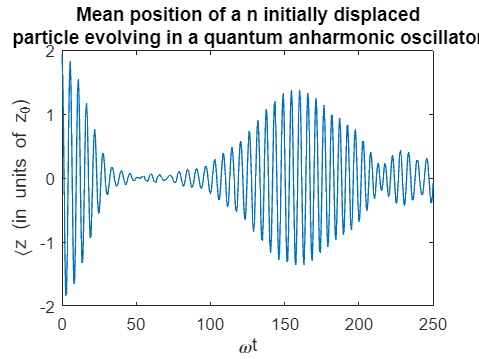

%Plotting just the mean of the position
plot(wtanhogrid,anhocohmeanmov(1,:));xlabel("\omega{t}");ylabel("\langle{z} (in units of z_0)");
title({"Mean position of a n initially displaced","particle evolving in a quantum anharmonic oscillator"})

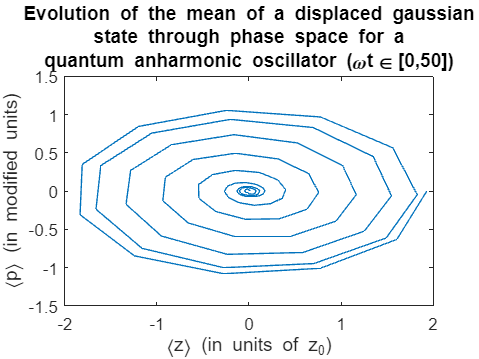

plot(anhocohmeanmov(1,1:101),anhocohmeanmov(2,1:101));
title({"Evolution of the mean of a displaced gaussian","state through phase space for a", "quantum anharmonic oscillator (\omega{t}\in[0,50])"});
xlabel("\langle{z}\rangle (in units of z_0)");ylabel("\langle{p}\rangle (in modified units)");

    The Wigner function of the "dissipated" state has negative values

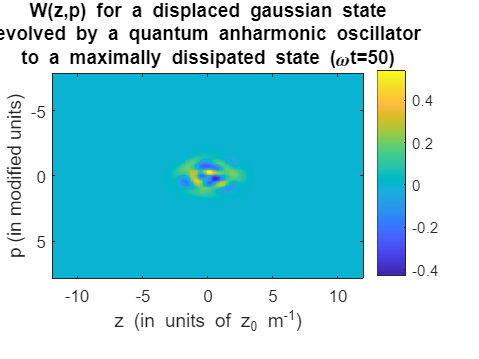

imagesc(modzgrid,modpgrid,W(anhocohmovie(101,:),dz));colorbar;daspect([1,1,1]);
title({"W(z,p) for a displaced gaussian state","evolved by a quantum anharmonic oscillator","to a maximally dissipated state (\omega{t}=50)"});
xlabel("z (in units of z_0 m^{-1})");ylabel("p (in modified units)");

    The Wigner function of the evolved state at the time of revival resemles its inital form

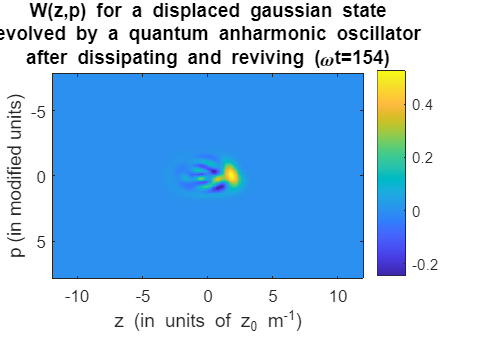

imagesc(modzgrid,modpgrid,W(anhocohmovie(310,:),dz));colorbar;daspect([1,1,1]);
title({"W(z,p) for a displaced gaussian state","evolved by a quantum anharmonic oscillator","after dissipating and reviving (\omega{t}=154)"});
xlabel("z (in units of z_0 m^{-1})");ylabel("p (in modified units)");

    Uncomment below to create an mp4 out of the entire evolution of the anharmonic oscillator (takes a few minutes)

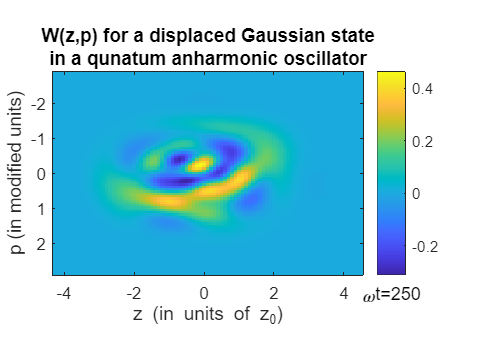

%Creating a movie out of the anharmonic oscillator evolution
% wigneranhocohmov=VideoWriter("wigneranhocohmov.mp4","MPEG-4");
% wigneranhocohmov.FrameRate=floor(nframes/3);
% open(wigneranhocohmov);
% for f=1:length(wtanhogrid);
%     wignermat=W(anhocohmovie(f,:),dz);
%     imagesc(modzgrid(pplotgridindices),modpgrid(pplotgridindices),wignermat(pplotgridindices, pplotgridindices));daspect([1,1,1]);colorbar;
%     title({"W(z,p) for a displaced Gaussian state", "in a qunatum anharmonic oscillator"});text(4.5,3.5,"\omega{t}="+num2str(wtanhogrid(f)));
%     xlabel("z (in units of z_0)");ylabel("p (in modified units)");
%     writeVideo(wigneranhocohmov,getframe(gcf));end;close(wigneranhocohmov);

## Functions

function int=gridint(grid,vals) 
    int=(grid(2:end)-grid(1:end-1))*(vals(:,2:end)+vals(:,1:end-1)).'/2; end
function eval=Hermite(grid,n) %Outputs the n^th Hermite polynomial evaluated recursively on the discrete grid grid.
    basecase=n<=0;
    if basecase
        eval=ones(1,length(grid));
    else
        assert(mod(n,1)==0 & n>=-1,"n must be a natural number"); 
        eval=2*grid.*Hermite(grid,n-1)-2*(n-1)*Hermite(grid,n-2);
    end
end
function [shosol, norm]=SHOmode(grid,n) %Returns the n^th normalized eigenmode of the
% quantum simple harmonic oscillator evaluated on grid, together with its pre-normalized L2 norm.
    assert(mod(n,1)==0 & n>=0,"n must be a natural number");
    shosol=Hermite(grid, n).*exp(-grid.^2/2); norm=sqrt(gridint(grid,abs(shosol).^2)); shosol=shosol/norm; end
function [outvals, modzgrid, modpgrid]=W(psi,dz) 
%Returns the Wigner function as a discrete 2D array (column corresp. position and rows to momentum) 
%associated with the input discritized wave function defined on a origin-centerd position grid with spacing dz.
    N=length(psi);npts=ceil(N^2/2)-2;
    samplepts=zeros(npts,2);values=zeros(npts,1);
    valindex=1;pmaxj=pi/(4*dz);
    for j=2:N-1
        spanj=[max(1,N-(2*(N-j))):min(N,1+2*(j-1))];Nj=length(spanj);
        % disp("j: "+num2str(j)+" spanj: "+num2str(spanj));
        rhoantidiagj=psi(spanj)'.'.*flip(psi(spanj));
        psj=linspace(-pmaxj,pmaxj,Nj).';psj=psj-psj(floor(Nj/2)+1);dpj=2*pmaxj/(Nj-1);
        zsj=((j-1)-(floor(N/2)+(mod(N,2)==0)))*dz*ones(Nj,1);
        values(valindex:valindex+Nj-1)=Nj*dz*2/pi*fftshift(ifft(ifftshift(rhoantidiagj)));
        samplepts(valindex:valindex+Nj-1,:)=[zsj,psj];
        valindex=valindex+Nj;end;
    % disp("Sample points: "+num2str(samplepts(1:valindex,:)));
    % disp("N^2: "+num2str(npts)+" Final valindex: "+num2str(valindex)+" Final Nj: "+num2str(Nj));
    Winterp=scatteredInterpolant(samplepts,values,"natural");
    modzgrid=(1-(floor(N/2)+(mod(N,2)==0)))*dz:dz:dz*(N-1-1-(floor(N/2)+(mod(N,2)==0)));modpgrid=linspace(-pmaxj,pmaxj,N);
    modpgrid=modpgrid-modpgrid(floor(N/2)+1);
    % [modzmesh,modpmesh]=meshgrid(modzgrid,modpgrid);
    outvals=Winterp({modzgrid,modpgrid}).';
end